## **Quick start into numerical differentiation using algebraic differentiators**

Algebraic differentiators are linear time-invariant filters with a finite-duration impulse response. These filters can be approximated as lowpass filters with a known cutoff frequency and a known stopband slope. They depend on 5 parameters: 

* the filter window length $$T$$

* the powers of the weight function of Jacobi polynomials $$\alpha$$ and $$\beta$$

* the truncation order of the generalized Fourier series $$N$$

* a delay parameter $$\vartheta$$.

The effects of the parameters can be very briefly summarized as follows (see the second notebook for a detailed discussion):

* Increasing $$T$$ decreases the effect of measurement disturbances but increases the error from the generalized Fourier series truncation. The filter window length $$T$$ can be computed from a desired cutoff frequency.

* Increasing $$N$$ decreases the error from the truncation of the generalized Fourier series expansion but increases the effect of measurement disturbances. A delay-free estimation is only possible for $$N>0$$. The accuracy is however decreased when the estimate is delay-free.

* The parameters $$\alpha$$ and $$\beta$$ have to satisfy $$\alpha,\beta>n-1$$, with $$n$$ the highest derivative order to be estimated. 

* In most applications, $$\alpha=\beta$$ is a good starting point. For large frequencies compared to the cutoff frequency, the signals are attenuated by $ $20\mu$$ dB per decade, with $$\mu=\min\{\alpha,\beta\}+1$$. For small window lengths, $$\alpha$$ and $$\beta$ $have to be chosen large to avoid any discretization effects. Always compare the amplitude spectrum of the continuous-time and discrete-time filters!

In the following example, the derivatives of a signal are estimated.

#### **Define an algebraic differentiator and get amplitude and phase spectra of the Fourier transform**

clear
close all

% Tell python where the class is
path2lib = '../';
if count(py.sys.path,path2lib) == 0
    insert(py.sys.path,int32(0),path2lib);
end





%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Initialize a differentiator with a desired cutoff 
% frequency  wc = 300 rad/s and filter order 5.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

ts = 0.001;
wc = 300;
T = string(missing);
% If you wan to specify the filter window length to the value T0
% change the last two code lines to:
% T = T0;
% wc = string(missing);
N = uint16(1);
alpha = 4.0;
beta = 4.0;
algDiff = py.algebraicDifferentiator.AlgebraicDifferentiator(...
                        ts,alpha,beta,N,T,wc);

The differentiator has the parameters:
Alpha: 4.000000
Beta: 4.000000
Window length in s: 0.030000
Polynomial degree: 1
Estimation delay in s: 0.010477
Cutoff Frequency: 306.068027
Discrete window length: 30



% For a delay-free estimation set N to 1 and uncomment the following line
% algDiff.set_theta(1,0)

% Discretization method
method = "trapezoidal";


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Frequency-domain analysis
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
omega = py.numpy.linspace(double(1),double(800),int16(10^3));

% Get phase and amplitude of Fourier transform of the continous 
% and discrete time filter for the estimation of the first 
% derivative.
% Note: get_ampAndPhaseFilter return the Fourier transform of the 
% continuous-time kernel. To compute the filter for the n-th 
% derivative multiply with (j\omega)^n with j the imaginary unit. 
% The function get_ampSpectrumDiscreteFilter returns the amplitude
% of the discrete-time filter for the specified derivative order.
Fourier = algDiff.get_ampAndPhaseFilter(omega);
ampCont = py.numpy.abs(Fourier{1}*(1j*omega));
phaseCont = Fourier{2}+py.numpy.angle((1j*omega));
FourierDis = algDiff.get_ampSpectrumDiscreteFilter(omega,1,method);

fi = figure('Position', [370 180 1240 720]);
tabF = uitab('Title', 'Frequency-domain analysis');
axF = axes('Parent',tabF,'Position',[.05,.08,.45,.85]);
hold(axF,'on');
plot(omega,ampCont,'Parent',axF,'LineWidth',2);
plot(omega,FourierDis{1},'--','Parent',axF,'LineWidth',2);
grid(axF,'on');
xlabel('$\omega$ in rad/s','Interpreter','latex');
ylabel('amplitude in dB','Interpreter','latex');
legend({'continuous filter','discretized filter'}, 'Interpreter', 'latex');
title('Amplitude spectrum');

axP = axes('Parent',tabF,'Position',[.54,.08,.45,.85]);
hold(axP,'on');
plot(omega,phaseCont,'Parent',axP,'LineWidth',2);
plot(omega,FourierDis{2},'--','Parent',axP,'LineWidth',2);
title('Phase spectrum');
grid(axP,'on');
xlabel('$\omega$ in rad/s','Interpreter','latex');
ylabel('phase in rad','Interpreter','latex');
legend({'continuous filter','discretized filter'}, 'Interpreter', 'latex');

#### Estimate the first derivative of a noisy sine function

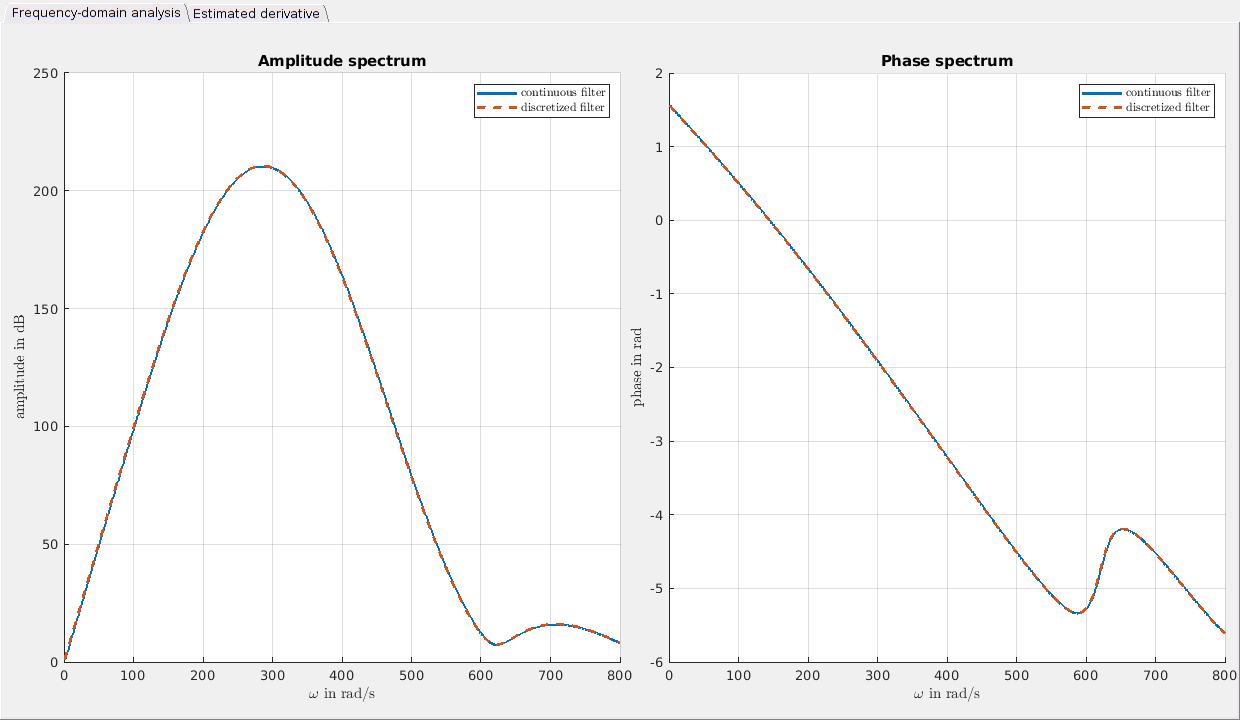

% Define signal x and its noisy observation y=x+noise and
% the derivative of x

t = 0:ts:5;
x = sin(25*t);
dx = 25*cos(25*t);
y = x+0.02*randn(size(t));

% Estimate 0-th and 1-st derivative of x using the measurement y
yApp = algDiff.estimateDer(0,y,method);
dyApp = algDiff.estimateDer(1,y,method);

tabx = uitab('Title', 'Estimated derivative');
axx = axes('Parent',tabx,'Position',[.05,.08,.45,.85]);
hold(axx,'on');
plot(t,x,'--','Parent',axx,'LineWidth',2);
plot(t,y,'Parent',axx,'LineWidth',2);
plot(t,yApp,'Parent',axx,'LineWidth',2);
grid(axx,'on');
xlabel('$t$','Interpreter','latex');
legend({'$x$','$y$','$\hat{x}$'}, 'Interpreter', 'latex');
title('Signals');

axdx = axes('Parent',tabx,'Position',[.54,.08,.45,.85]);
hold(axdx,'on');
plot(t,dx,'Parent',axdx);
plot(t,dyApp,'Parent',axdx);
title('Derivatives');
grid(axdx,'on');
xlabel('$t$','Interpreter','latex');
legend({'$\dot{x}$','$\hat{\dot{x}}$'}, 'Interpreter', 'latex');

#### Extracting filter coefficient for an estimation on embedded systems

In most embedded applications of algebraic differentiators, the measured signal $$y$$ is available at discrete sampling instants only. Then, the finite convolution integral of the estimation (see the extended examples) must be approximated by an appropriate quadrature method. This yields discrete FIR filters, whose implementation is favourable in terms of numerical stability.

Let $$t_{\mathrm{s}}$$ be the sampling period. For the sake of brevity, the abbreviation $$f_i = f(i t_{\mathrm{s}})$$, $$i\in\mathbb{N}$
$, for a sample of a function $$f$$ at time $$i t_{\mathrm{s}}$$ is used in the following. Then, various  discrete-time approximations yield at a step $$k$
$ an estimate of the form


$$\hat{y}^{(n)}_{k}=\sum_{i=0}^{L-1}w_iy_{k-i},\quad\quad k\geq L,
$$


where $$L$$, the number of filter coefficients, and $$w_i$$, $$i=0,...,L$$, the filter coefficients, depend on the used numerical integration method. For more details see the documentation of the class and the corresponding literature.

The following example shows how to get the filter coefficients $$w_i$$, $$i=0,...,L$$, using a given discretization method.

% If you want to get the filter coefficients to estimate the first
% derivative fo the following
coeff = algDiff.discretize(1,method);
w = double(coeff{1}{'trapezoidal'});